clc
clear

Time Response for Simple Transfer Function

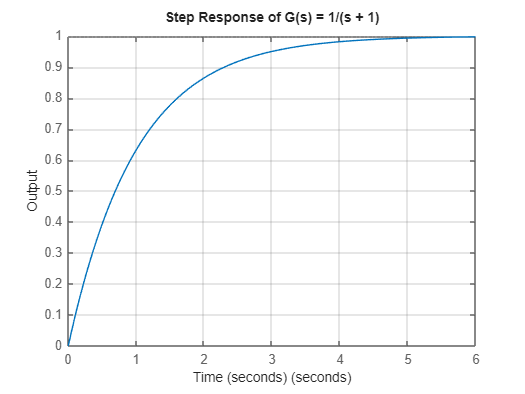

K = 1;        % Gain
a = 1;        % Pole locations

s = tf('s');
G = K / (s + a);

figure
step(G)
title(['Step Response of G(s) = ' ...
    num2str(K) '/(s + ' num2str(a) ')'])
xlabel('Time (seconds)')
ylabel('Output')
grid on

Time Response Behavior for Change in Pole Location 'a'

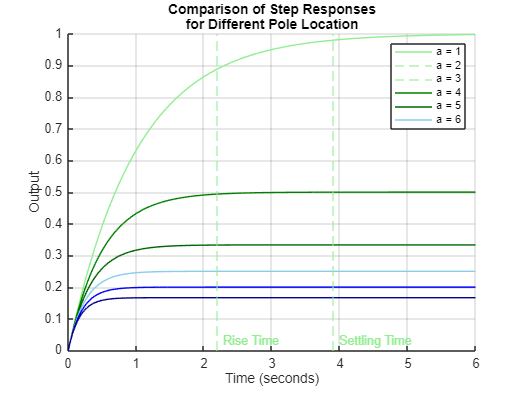

K = 1;                      % Constant gain
a_values = [1 2 3 4 5 6];   % Pole locations
color_values = [
    0.565, 0.933, 0.565;  % Light Green
    0.000, 0.502, 0.000;  % Medium Green
    0.000, 0.392, 0.000;  % Dark Green
    0.529, 0.808, 0.922;  % Light Blue
    0.000, 0.000, 1.000;  % Medium Blue
    0.000, 0.000, 0.545   % Dark Blue
];

s = tf('s');
t_final = 6;    % End of response time (s)
t = linspace(0,t_final,1000); 

figure
hold on

for i = 1:length(a_values)
    a = a_values(i);
    G = K / (s + a);
    [y, ~] = step(G,t);  % Extract response data
    plot(t, y, 'Color', color_values(i, :));
    
    if i == 1
        % Step info
        info = stepinfo(G, 'RiseTimeLimits', [0.1, 0.9]);
        
        % Plot vertical dashed line at rise time
        xline(info.RiseTime, '--', 'Rise Time', ...
            'Color', color_values(i, :), ...
            'LabelOrientation', 'horizontal', ...
            'LabelVerticalAlignment', 'bottom');
        % Plot vertical dashed line at settling time
        xline(info.SettlingTime, '--', 'Settling Time', ...
            'Color', color_values(i, :), ...
            'LabelOrientation', 'horizontal', ...
            'LabelVerticalAlignment', 'bottom');
    end

end

% Dynamically generate legend entries in the format 'a = x'
legend_labels = arrayfun(@(a) ['a = ' num2str(a)], ...
    a_values, 'UniformOutput', false);
legend(legend_labels)

title({'Comparison of Step Responses', 'for Different Pole Location'});
xlabel('Time (seconds)')
ylabel('Output')
grid on
hold off

Rise and Settling Time Behaviors

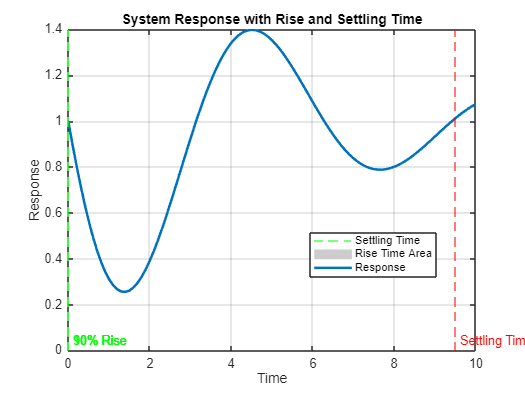

% Sample data for the plot (you can replace this with your actual data)
time = 0:0.1:10;  % Time vector
response = 1 - exp(-0.2 * time) .* sin(time);  % Example response (like a damped sine wave)

% Final value of the response (for rise time and settling time calculation)
final_value = 1;

% Calculate rise time (time to go from 10% to 90% of final value)
rise_time_start = find(response >= 0.1 * final_value, 1);  % 10% of final value
rise_time_end = find(response >= 0.9 * final_value, 1);    % 90% of final value
rise_time = time(rise_time_end) - time(rise_time_start);  % Difference gives rise time

% Calculate settling time (time when the response stays within 2% of final value)
settling_time_threshold = 0.02 * final_value;
settling_time_index = find(abs(response - final_value) <= settling_time_threshold, 1, 'last');
settling_time = time(settling_time_index);

% Plot the response
figure;
plot(time, response, 'LineWidth', 2);
hold on;

% Plot rise time area (from 10% to 90% of final value)
area(time(rise_time_start:rise_time_end), response(rise_time_start:rise_time_end), 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');

% Plot vertical dashed lines for rise time
xline(time(rise_time_start), '--', '10% Rise', 'Color', 'g', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom');
xline(time(rise_time_end), '--', '90% Rise', 'Color', 'g', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom');

% Plot vertical dashed line for settling time
xline(settling_time, '--', 'Settling Time', 'Color', 'r', 'LabelOrientation', 'horizontal', 'LabelVerticalAlignment', 'bottom');

% Additional plot formatting
xlabel('Time');
ylabel('Response');
title('System Response with Rise and Settling Time');
legend({'Response', 'Rise Time Area', 'Settling Time'}, 'Location', 'best');
grid on;
hold off;


% Display rise and settling time values
fprintf('Rise Time: %.2f seconds\n', rise_time);

Rise Time: 0.00 seconds


fprintf('Settling Time: %.2f seconds\n', settling_time);

Settling Time: 9.50 seconds
